## PageRank algorithm

pagerank_urls.txt: each line has URL of a web page, N URLs

pagerank_adj.mat: imports an adjacency matrix J (NxN matrix with value 1 if there is a connection between the pages)

No links from a page to itself

clear all;
load('pagerank_adj.mat');

## Finding link matrix

denominator = sum(J); % sum of all the columns
A = J ./ denominator;

% verifying that columns sum to 1
sum(A)

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



% we are essentially normalizing J to find the weights of each possible page connection with respect to the total amount of page connections

## Power Iteration Algorithm

x(k+1) : approximation of the eigenvector in the k+i iteration

e(k+1) = || A x(k+1) - x(k+1) || : approximation error

Run this for 10 iterations

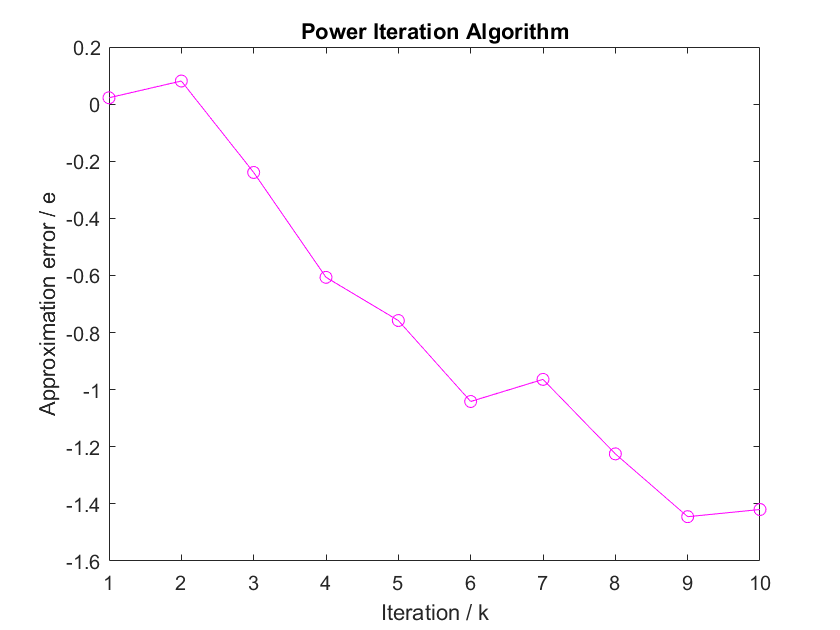

%% initialization
k = 10; %iterations
N = size(A, 2); %2571
x = zeros([N 1]);
x(1,:) = 1; %set first x to 1
error = zeros([1 k]);

% finding x(k+1) and error for every k
for i = 1:k
    x_n = A*x / norm(A*x);
    eigenval = x_n' * A*x_n;
    error(i) = norm(A*x - x);
    x = x_n;
end
plot(1:10, log(error), 'mo-')
title('Power Iteration Algorithm')
xlabel('Iteration / k')
ylabel('Approximation error / e')

## Shift-invert power iteration and Rayleigh quotient

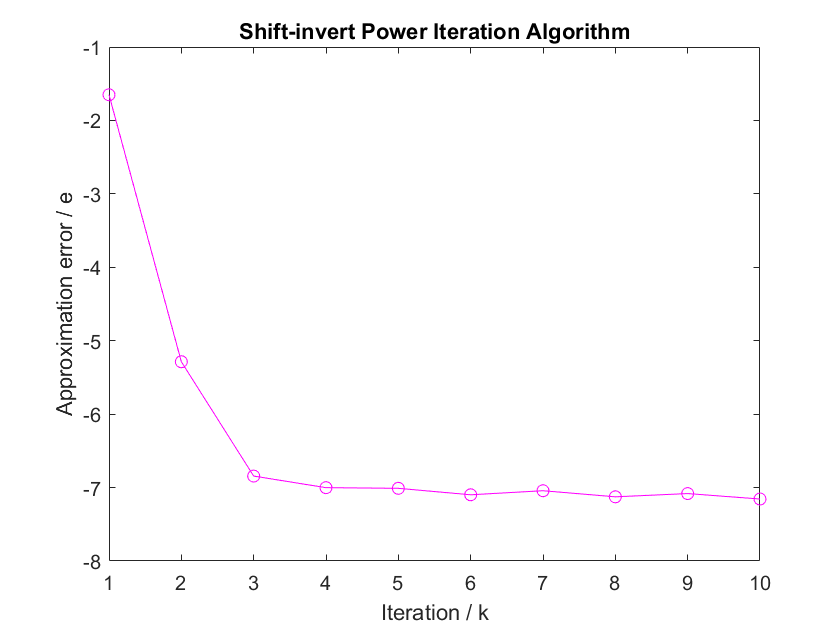

%% Shift-invert power iteration
sigma = 0.99;
for i=1:k
    x_n = inv(A - sigma * eye(N)) * x;
    x_n = x_n / norm(x_n);
    eigenval = x_n' * A*x_n;
    error(i) = norm(A*x - x);
    x = x_n;
end
plot(1:10, log(error), 'mo-')
title('Shift-invert Power Iteration Algorithm')
xlabel('Iteration / k')
ylabel('Approximation error / e')

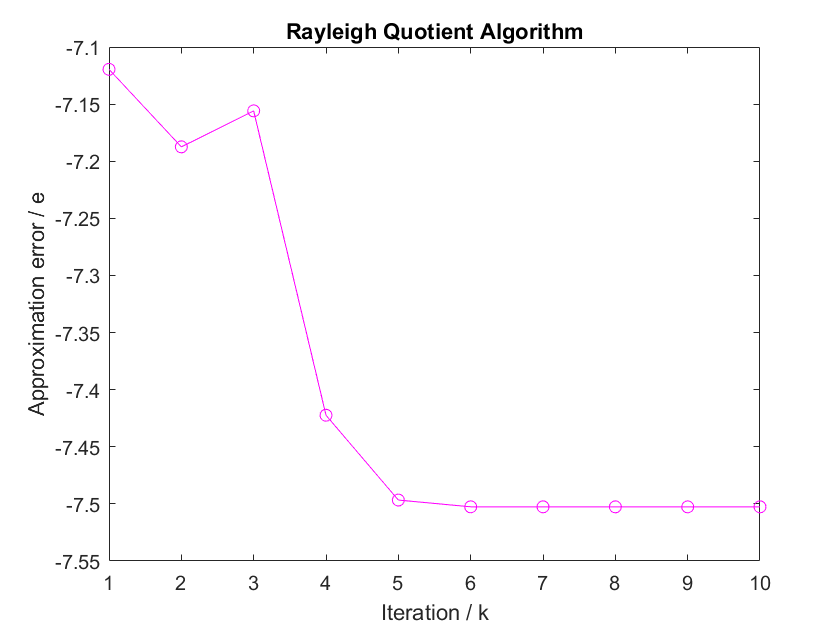


%% Rayleigh quotient
error = zeros([1 k]);
for i=1:k
    if i==1 || i ==2
        sigma = 0.99;
    else
        sigma = (x' *A*x)/(x' * x);
    end
    x_n = inv(A-sigma*eye(N))*x;
    x_n = x_n /norm(x_n);
    
    error(i) = norm(A*x - x);
    x = x_n;
    k= k + 1;
end
plot(1:10, log(error), 'mo-')
title('Rayleigh Quotient Algorithm')
xlabel('Iteration / k')
ylabel('Approximation error / e')